Demo code for Figure 2 of Idesis (2022) - Introducing structural disconnection masks in whole-brain models. A mechanistic explanation of stroke patients effective connectivity

Adapted by: Sebastian Idesis - sebastian.idesis@upf.edu (Feb 2022)

Initialize script

clear all;close all;clc; %Close everything

Add helper functions and data to path

addpath('Functions');
addpath('Data');

Load Time series, Structural connectivity and effective connectivity

load Data_Hopf_model.mat %Demo data (Only 2 subjects per group)
load('FC_sim_patients.mat') %Obtained in the previous script (Fig_1b)
load('Networks_Demo.mat')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%% INTRAHEMISPHERIC %%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Define which nodes correspond to the areas of interest

left_dan=[31:43];
left_dmn=[74:100];
right_dan=[135:147];
right_dmn=[182:200];

Intrahemishpheric Controls (Empirical)

intrahemispheric_controls_emp = zeros(1,size(TS_Controls,3));
for subj = 1:size(TS_Controls,3)
    ts = TS_Controls(:,:,subj);
    fc=corrcoef(ts');
    table_temp_left = fc(left_dan,left_dmn);
    table_temp_right = fc(right_dan,right_dmn);
    
    corr_left = nanmean(nanmean((table_temp_left)));
    corr_right= nanmean(nanmean((table_temp_right)));
    corr_controls =[corr_left corr_right];
    intrahemispheric_controls_emp(subj) = mean(corr_controls);
end

Intrahemishpheric Patients (Empirical)

intrahemispheric_patients_emp = zeros(1,size(TS_patients,3));
for subj = 1:size(TS_patients,3)
    ts = TS_patients(:,:,subj);
    fc=corrcoef(ts');
    table_temp_left = fc(left_dan,left_dmn);
    table_temp_right = fc(right_dan,right_dmn);
    
    corr_left = nanmean(nanmean((table_temp_left)));
    corr_right= nanmean(nanmean((table_temp_right)));
    corr_patients =[corr_left corr_right];
    intrahemispheric_patients_emp(subj) = mean(corr_patients);
end

Intrahemishpheric Patients (Simulated)

intrahemispheric_patients_sim = zeros(1,size(FCsim_accumulated,3));
for subj = 1:size(FCsim_accumulated,3)
    fc=FCsim_accumulated(:,:,subj);
    table_temp_left = fc(left_dan,left_dmn);
    table_temp_right = fc(right_dan,right_dmn);
    
    corr_left = nanmean(nanmean((table_temp_left)));
    corr_right= nanmean(nanmean((table_temp_right)));
    corr_patients =[corr_left corr_right];
    intrahemispheric_patients_sim(subj) = mean(corr_patients);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%% INTERHEMISPHERIC %%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Define which nodes correspond to the areas of interest (11 networks Left and Right)

l1=[1:14]; l2=[15:30]; l3=[31:43]; l4=[44:54]; l5=[55:60]; l6=[61:73];
l7=[74:100]; l8=[201 203 205]; l9=[207]; l10=[209:2:233]; l11=[235];

r1=[101:115]; r2=[116:134]; r3=[135:147]; r4=[148:158]; r5=[159:164];
r6=[165:181]; r7=[182:200]; r8=[202 204 206]; r9=[208]; r10=[210:2:234]; r11=[235];

 Interhemispheric level - patients (Empirical)

interhemispheric_patients_emp = zeros(1,size(TS_patients,3));
for subj = 1:size(TS_patients,3)
    ts = TS_patients(:,:,subj);
    fc=corrcoef(ts');
    corr_inter=[];
    for area = 1:11
        varL = strcat('l',num2str(area));
        varR = strcat('r',num2str(area));
        corr_inter(end+1) = nanmean(nanmean(fc(eval(varL), eval(varR))));
    end
    interhemispheric_patients_emp(subj) = nanmean(corr_inter);
end

 Interhemispheric level - controls (Empirical)

interhemispheric_patients_emp = zeros(1,size(TS_Controls,3));
for subj = 1:size(TS_Controls,3)
    ts = TS_Controls(:,:,subj);
    fc=corrcoef(ts');
    corr_inter=[];
    for area = 1:11
        varL = strcat('l',num2str(area));
        varR = strcat('r',num2str(area));
        corr_inter(end+1) = nanmean(nanmean(fc(eval(varL), eval(varR))));
    end
    interhemispheric_controls_emp(subj) = nanmean(corr_inter);
end

 Interhemispheric level - patients (Simulated)

interhemispheric_patients_sim = zeros(1,size(FCsim_accumulated,3));
for subj = 1:size(FCsim_accumulated,3)
    fc=corrcoef(FCsim_accumulated(:,:,subj));
    corr_inter=[];
    for area = 1:11
        varL = strcat('l',num2str(area));
        varR = strcat('r',num2str(area));
        corr_inter(end+1) = nanmean(nanmean(fc(eval(varL), eval(varR))));
    end
    interhemispheric_patients_sim(subj) = nanmean(corr_inter);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%% MODULARITY %%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Modularity Patients (Empirical)

for subj = 1:size(TS_patients,3)
    ts = TS_patients(:,:,subj); fc=corrcoef(ts'); FC(:,:,subj) = fc;
end
n = 235; % # ROIs
NET_new.net_reduced = Networks(:); n_Sbj = size(TS_patients,3);

% Masks definition
mask   = triu(ones(n, n), 1); i_mask = find(mask); l_mask = length(i_mask); [r_i, c_i] = ind2sub([n n], i_mask);
idx_mod = find(NET_new.net_reduced <= 8); % NET_new.net_reduced contains the network index for each node (only cortical)
net = NET_new.net_reduced(idx_mod);

% mask
mask_mod   = triu(ones(length(idx_mod)), 1); i_mask_mod = find(mask_mod); l_mask_mod = length(i_mask_mod);
[r_i_mod, c_i_mod] = ind2sub([length(idx_mod) length(idx_mod)], i_mask_mod);

% Density definition
prc     = 4 : 4 : 50; n_prc   = length(prc); val_prc = ceil(l_mask_mod .* .5 .* prc ./ 100);
eval_modularity=true;
% Symmetric-negative modularity
if eval_modularity
    Modularity_static_sym_neg = nan(n_Sbj, n_prc);
    for is = 1 : n_Sbj
            mat = squeeze(FC(:, :, is)); mat = mat(idx_mod, idx_mod); mat(isinf(mat)) = 0; mat(isnan(mat)) = 0;
           
            val_sort = sort(abs(mat(i_mask_mod)), 'descend');
           
            for ip = 1 : n_prc
                val_ip = val_sort(val_prc(ip)); mat_ip = mat; mat_ip(abs(mat_ip) < val_ip) = 0;
                Modularity_static_sym_neg(is, ip) = community_louvain_apriori(mat_ip, 1, net, 'negative_sym');
            end
    end
end
Modularity_emp_patients = mean(Modularity_static_sym_neg, 2);

Modularity Controls (Empirical)

for subj = 1:size(TS_Controls,3)
    ts = TS_Controls(:,:,subj); fc=corrcoef(ts'); FC(:,:,subj) = fc;
end
n = 235; % # ROIs
NET_new.net_reduced = Networks(:); n_Sbj = size(TS_Controls,3);

% Masks definition
mask   = triu(ones(n, n), 1); i_mask = find(mask); l_mask = length(i_mask); [r_i, c_i] = ind2sub([n n], i_mask);
idx_mod = find(NET_new.net_reduced <= 8); % NET_new.net_reduced contains the network index for each node (only cortical)
net = NET_new.net_reduced(idx_mod);

% mask
mask_mod   = triu(ones(length(idx_mod)), 1); i_mask_mod = find(mask_mod); l_mask_mod = length(i_mask_mod);
[r_i_mod, c_i_mod] = ind2sub([length(idx_mod) length(idx_mod)], i_mask_mod);

% Density definition
prc     = 4 : 4 : 50; n_prc   = length(prc); val_prc = ceil(l_mask_mod .* .5 .* prc ./ 100);
eval_modularity=true;
% Symmetric-negative modularity
if eval_modularity
    Modularity_static_sym_neg = nan(n_Sbj, n_prc);
    for is = 1 : n_Sbj
            mat = squeeze(FC(:, :, is)); mat = mat(idx_mod, idx_mod); mat(isinf(mat)) = 0; mat(isnan(mat)) = 0;
           
            val_sort = sort(abs(mat(i_mask_mod)), 'descend');
           
            for ip = 1 : n_prc
                val_ip = val_sort(val_prc(ip)); mat_ip = mat; mat_ip(abs(mat_ip) < val_ip) = 0;
                Modularity_static_sym_neg(is, ip) = community_louvain_apriori(mat_ip, 1, net, 'negative_sym');
            end
    end
end
Modularity_emp_controls = mean(Modularity_static_sym_neg, 2);

Modularity Patients (Empirical)

for subj = 1:size(FCsim_accumulated,3)
    FC = FCsim_accumulated;
end
n = 235; % # ROIs
NET_new.net_reduced = Networks(:); n_Sbj = size(FCsim_accumulated,3);

% Masks definition
mask   = triu(ones(n, n), 1); i_mask = find(mask); l_mask = length(i_mask); [r_i, c_i] = ind2sub([n n], i_mask);
idx_mod = find(NET_new.net_reduced <= 8); % NET_new.net_reduced contains the network index for each node (only cortical)
net = NET_new.net_reduced(idx_mod);

% mask
mask_mod   = triu(ones(length(idx_mod)), 1); i_mask_mod = find(mask_mod); l_mask_mod = length(i_mask_mod);
[r_i_mod, c_i_mod] = ind2sub([length(idx_mod) length(idx_mod)], i_mask_mod);

% Density definition
prc     = 4 : 4 : 50; n_prc   = length(prc); val_prc = ceil(l_mask_mod .* .5 .* prc ./ 100);
eval_modularity=true;
% Symmetric-negative modularity
if eval_modularity
    Modularity_static_sym_neg = nan(n_Sbj, n_prc);
    for is = 1 : n_Sbj
            mat = squeeze(FC(:, :, is)); mat = mat(idx_mod, idx_mod); mat(isinf(mat)) = 0; mat(isnan(mat)) = 0;
           
            val_sort = sort(abs(mat(i_mask_mod)), 'descend');
           
            for ip = 1 : n_prc
                val_ip = val_sort(val_prc(ip)); mat_ip = mat; mat_ip(abs(mat_ip) < val_ip) = 0;
                Modularity_static_sym_neg(is, ip) = community_louvain_apriori(mat_ip, 1, net, 'negative_sym');
            end
    end
end
Modularity_sim_patients = mean(Modularity_static_sym_neg, 2);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%% VISUALIZATION%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Intrahemispheric

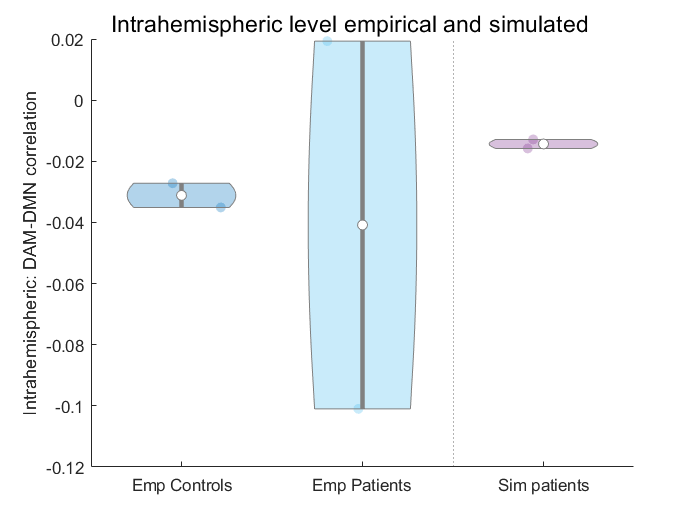

figure()
temp_combined = [intrahemispheric_controls_emp intrahemispheric_patients_emp...
    intrahemispheric_patients_sim];
group = [zeros(1,length(intrahemispheric_controls_emp)),...
    ones(1,length(intrahemispheric_patients_emp)),...
    (ones(1,length(intrahemispheric_patients_sim))*2)];

vs = violinplot(temp_combined, group);
xticklabels({'Emp Controls','Emp Patients','Sim patients'})
ylabel('Intrahemispheric: DAM-DMN correlation')
title('')
xline(2.5,':')
sgtitle('Intrahemispheric level empirical and simulated')

Interhemispheric

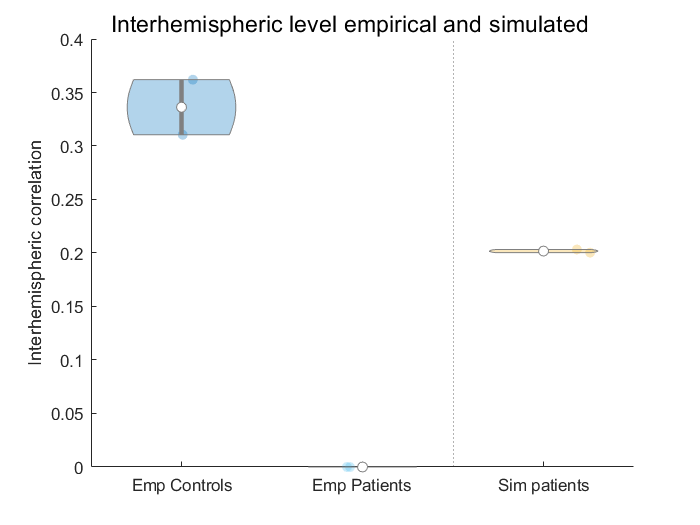

figure()
temp_combined = [interhemispheric_controls_emp interhemispheric_patients_emp...
    interhemispheric_patients_sim];
group = [zeros(1,length(interhemispheric_controls_emp)),...
    ones(1,length(interhemispheric_patients_emp)),...
    (ones(1,length(interhemispheric_patients_sim))*2)];

vs = violinplot(temp_combined, group);
xticklabels({'Emp Controls','Emp Patients','Sim patients'})
ylabel('Interhemispheric correlation')
title('')
xline(2.5,':')
sgtitle('Interhemispheric level empirical and simulated')

Modularity

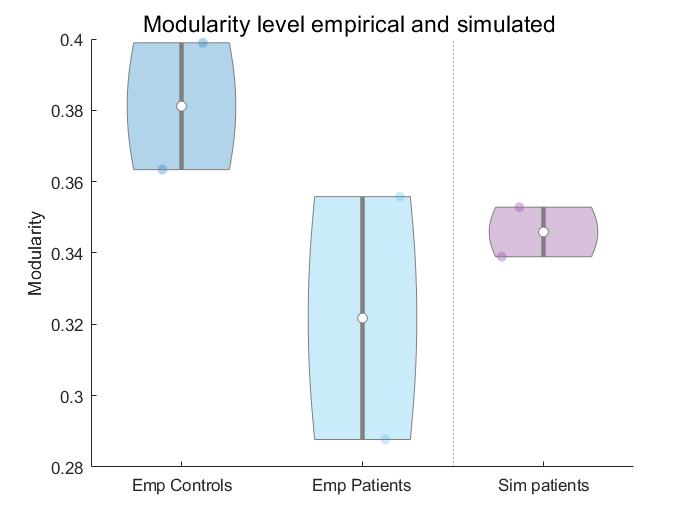

figure()
temp_combined = [Modularity_emp_controls Modularity_emp_patients...
    Modularity_sim_patients];
group = [zeros(1,length(Modularity_emp_controls)),...
    ones(1,length(Modularity_emp_patients)),...
    (ones(1,length(Modularity_sim_patients))*2)];

vs = violinplot(temp_combined, group);
xticklabels({'Emp Controls','Emp Patients','Sim patients'})
ylabel('Modularity')
title('')
xline(2.5,':')
sgtitle('Modularity level empirical and simulated')